## A: Now, with drive+LDE

### A1. Prepair parameters for drive simulation

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
    OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
    OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
    OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
    OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
    OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
    OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

% Ver1
% L6Ord_F = [50 33 15 33];
% Ver 4
L6Ord_F = [50 31 12 31];
L6S_Drive = L6Ord_F*NS_L6/1e3 * StimulusFac;
L6C_Drive = L6Ord_F*NC_L6/1e3 * StimulusFac;
L6I_Drive = L6Ord_F*NI_L6/1e3 * StimulusFac;

% NOTE: Doing Gaussian blur
FigOn = false;
L6SFilt = SpatialGaussianFilt(OD_SMap,L6S_Drive,n_S_HC/8,FigOn);
L6CFilt = SpatialGaussianFilt(OD_CMap,L6C_Drive,n_C_HC/8,FigOn);
L6IFilt = SpatialGaussianFilt(OD_IMap,L6I_Drive,n_I_HC/8,FigOn);

rE_L6_Drive = [L6SFilt;L6CFilt];
rI_L6_Drive = L6IFilt;


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

### A2. Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000;
% E-to-E delay time
T_EEDly = .1; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .1; N_IEDly = floor(T_IEDly/dt); %% NOTE: Was both 0.5
T_EIDly = .1; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
    'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState('InSStr', InSStr,N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))];
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))];
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
    'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
    'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
    'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
    tic
    for TimeN = 1:floor(T/dt/TPar)
        % Zero: Use Phase vec to determine different lgn phases for E neurons
        PhaseE = mod(PhaseE + dt,tMod);
        % First, Get input matrices from series
        InpWin = 100; FrameNum = floor(InpWin/dt);
        FrameInd = mod(TimeN, FrameNum);
        if FrameInd == 0
            FrameInd = FrameNum;
        end
        RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
        if FrameInd  == 1 % if the first frame, recompute input mats
            tt = 0:dt:InpWin-dt;
            AdjlgnE = PhaseFRS(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
            AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
            EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
            IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa

            EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); %
            InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));

        end


        %      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
        %      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
        %      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
        [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
            oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
            oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
            oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
            oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
            V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
            GE_ampa_D,GE_nmda_D,GE_gaba_D,...
            RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
            GI_ampa_D,GI_nmda_D,GI_gaba_D,...
            EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
            C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
            S_EE,S_EI,S_IE,S_II,...
            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
            dt,p_EEFail,...
            gL_E,Ve,rhoE_ampa,rhoE_nmda,...
            gL_I,Vi,rhoI_ampa,rhoI_nmda,...
            EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
            EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
        % iteration
        RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
        GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
        RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
        GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
        EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

        % Record Every Time time window
        RecordNum = floor(sampleT/dt);
        RecordInd = mod(TimeN, RecordNum);
        SampleRate = 0.1; % Can't be too small for multiple phases
        if RecordInd == 1
            clear E_Sp I_Sp mVETemp mVITemp
            E_Sp = [];
            I_Sp = [];
            mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            mVRecordInd = 1;
        elseif RecordInd == 0
            NWTrace(SampleInd).mVEs = mVETemp;
            NWTrace(SampleInd).mVIs = mVITemp;

            NWTrace(SampleInd).SpEs = E_Sp;
            NWTrace(SampleInd).SpIs = I_Sp;

            NWTrace(SampleInd).GE_I = GE_ITemp;
            NWTrace(SampleInd).GE_E = GE_ETemp;
            NWTrace(SampleInd).GI_I = GI_ITemp;
            NWTrace(SampleInd).GI_E = GI_ETemp;
            SampleInd = SampleInd + 1
            %sum(isnan(oVE))/N_E
            FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
            FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
            FrINow = size(I_Sp,1)/N_I/sampleT*1000
            toc
        end
        E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
        I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);

        if mod(TimeN,floor(1/SampleRate)) == 5
            mVETemp(:,mVRecordInd) = oVE;
            mVITemp(:,mVRecordInd) = oVI;
            % Precompute GE GI
            GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
            GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
                1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %

            GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
            GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
                1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %
            GE_ITemp(:,mVRecordInd) = GE_I;
            GE_ETemp(:,mVRecordInd) = GE_E;
            GI_ITemp(:,mVRecordInd) = GI_I;
            GI_ETemp(:,mVRecordInd) = GI_E;
            %record loop goes forward
            mVRecordInd = mVRecordInd + 1;
        end

        if sum(isnan(oVE))>0.80*N_E
            BlowUp = true;
            disp('warning!: Network exploded')
            break
        end

        % the end of iteration
    end
    toc
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
        RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
        EEDlyRcd, IEDlyRcd};
    save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

    clear NWTrace
    NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
        'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
        'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
        'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 8.7627

FrECNow = 12.6716

FrINow = 43.6929

Elapsed time is 2.418568 seconds.


SampleInd = 3

FrESNow = 9.3926

FrECNow = 22.6519

FrINow = 51.4348

Elapsed time is 4.219831 seconds.


SampleInd = 4

FrESNow = 9.0206

FrECNow = 22.7654

FrINow = 51.2360

Elapsed time is 6.762750 seconds.


SampleInd = 5

FrESNow = 9.3728

FrECNow = 28.0963

FrINow = 55.9070

Elapsed time is 8.598161 seconds.


SampleInd = 6

FrESNow = 8.9822

FrECNow = 25.6123

FrINow = 53.8004

Elapsed time is 11.155736 seconds.


SampleInd = 7

FrESNow = 8.8889

FrECNow = 26.7753

FrINow = 54.2144

Elapsed time is 12.952263 seconds.


SampleInd = 8

FrESNow = 8.5531

FrECNow = 23.6617

FrINow = 52.5194

Elapsed time is 15.480531 seconds.


SampleInd = 9

FrESNow = 8.9942

FrECNow = 27.7111

FrINow = 55.4052

Elapsed time is 17.349782 seconds.


SampleInd = 10

FrESNow = 9.1918

FrECNow = 31.2395

FrINow = 58.3351

Elapsed time is 20.112910 seconds.


SampleInd = 11

FrESNow = 8.6650

FrECNow = 23.3111

FrINow = 52.7344

Elapsed time is 22.017298 seconds.


SampleInd = 12

FrESNow = 8.9492

FrECNow = 28.9432

FrINow = 56.3672

Elapsed time is 24.680566 seconds.


SampleInd = 13

FrESNow = 8.5432

FrECNow = 26.4790

FrINow = 54.7000

Elapsed time is 26.603235 seconds.


SampleInd = 14

FrESNow = 8.4422

FrECNow = 26.2074

FrINow = 53.9161

Elapsed time is 29.116401 seconds.


SampleInd = 15

FrESNow = 9.5012

FrECNow = 30.9457

FrINow = 58.6264

Elapsed time is 31.032725 seconds.


SampleInd = 16

FrESNow = 8.7440

FrECNow = 26.9481

FrINow = 54.9381

Elapsed time is 33.635324 seconds.


SampleInd = 17

FrESNow = 8.6266

FrECNow = 26.4395

FrINow = 54.0386

Elapsed time is 35.516809 seconds.


SampleInd = 18

FrESNow = 8.7824

FrECNow = 24.6247

FrINow = 53.7056

Elapsed time is 38.002471 seconds.


SampleInd = 19

FrESNow = 8.6036

FrECNow = 26.4840

FrINow = 53.9392

Elapsed time is 39.787225 seconds.


SampleInd = 20

FrESNow = 9.1545

FrECNow = 30.9580

FrINow = 58.1616

Elapsed time is 42.412475 seconds.


SampleInd = 21

FrESNow = 8.4982

FrECNow = 23.1111

FrINow = 51.8603

Elapsed time is 44.217776 seconds.


Elapsed time is 44.218770 seconds.


SampleInd = 22

FrESNow = 8.9822

FrECNow = 27.3284

FrINow = 54.8942

Elapsed time is 2.505095 seconds.


SampleInd = 23

FrESNow = 9.0974

FrECNow = 29.7383

FrINow = 57.3685

Elapsed time is 4.356247 seconds.


SampleInd = 24

FrESNow = 8.4291

FrECNow = 23.5630

FrINow = 51.9829

Elapsed time is 6.903564 seconds.


SampleInd = 25

FrESNow = 9.0283

FrECNow = 26.4938

FrINow = 54.7416

Elapsed time is 8.797230 seconds.


SampleInd = 26

FrESNow = 8.9756

FrECNow = 27.8321

FrINow = 55.8816

Elapsed time is 11.367243 seconds.


SampleInd = 27

FrESNow = 8.8713

FrECNow = 26.8568

FrINow = 54.9890

Elapsed time is 13.311842 seconds.


SampleInd = 28

FrESNow = 8.5443

FrECNow = 26.4938

FrINow = 54.0224

Elapsed time is 15.952576 seconds.


SampleInd = 29

FrESNow = 8.8132

FrECNow = 27.7901

FrINow = 55.6804

Elapsed time is 17.887938 seconds.


SampleInd = 30

FrESNow = 8.9185

FrECNow = 27.3975

FrINow = 55.5833

Elapsed time is 20.512956 seconds.


SampleInd = 31

FrESNow = 9.1413

FrECNow = 29.2543

FrINow = 57.0702

Elapsed time is 22.389595 seconds.


SampleInd = 32

FrESNow = 8.8209

FrECNow = 28.4247

FrINow = 56.3718

Elapsed time is 24.968441 seconds.


SampleInd = 33

FrESNow = 9.0612

FrECNow = 30.9654

FrINow = 58.2333

Elapsed time is 26.918450 seconds.


SampleInd = 34

FrESNow = 8.4159

FrECNow = 22.3062

FrINow = 51.9482

Elapsed time is 29.399710 seconds.


SampleInd = 35

FrESNow = 8.8406

FrECNow = 26.5778

FrINow = 55.1301

Elapsed time is 31.249689 seconds.


SampleInd = 36

FrESNow = 8.9163

FrECNow = 26.0222

FrINow = 54.1196

Elapsed time is 33.869963 seconds.


SampleInd = 37

FrESNow = 8.7649

FrECNow = 28.1728

FrINow = 55.6365

Elapsed time is 35.680945 seconds.


SampleInd = 38

FrESNow = 8.4587

FrECNow = 26.2222

FrINow = 54.0733

Elapsed time is 38.189672 seconds.


SampleInd = 39

FrESNow = 8.9328

FrECNow = 28.4025

FrINow = 56.4412

Elapsed time is 40.062476 seconds.


SampleInd = 40

FrESNow = 8.7583

FrECNow = 27.4123

FrINow = 55.5347

Elapsed time is 42.665078 seconds.


SampleInd = 41

FrESNow = 8.6123

FrECNow = 25.2173

FrINow = 53.9346

Elapsed time is 44.478063 seconds.


Elapsed time is 44.478858 seconds.


SampleInd = 42

FrESNow = 9.2126

FrECNow = 28.6049

FrINow = 56.5661

Elapsed time is 2.617900 seconds.


SampleInd = 43

FrESNow = 8.0626

FrECNow = 25.2148

FrINow = 52.7714

Elapsed time is 4.456178 seconds.


SampleInd = 44

FrESNow = 9.0678

FrECNow = 30.4691

FrINow = 57.7824

Elapsed time is 7.074604 seconds.


SampleInd = 45

FrESNow = 9.0776

FrECNow = 24.6840

FrINow = 54.3785

Elapsed time is 8.866279 seconds.


SampleInd = 46

FrESNow = 8.6145

FrECNow = 27.9210

FrINow = 55.5810

Elapsed time is 11.393945 seconds.


SampleInd = 47

FrESNow = 8.9591

FrECNow = 28.3827

FrINow = 55.9556

Elapsed time is 13.276993 seconds.


SampleInd = 48

FrESNow = 8.3007

FrECNow = 22.6617

FrINow = 51.0001

Elapsed time is 15.726946 seconds.


SampleInd = 49

FrESNow = 8.8735

FrECNow = 28.0395

FrINow = 55.6457

Elapsed time is 17.576801 seconds.


SampleInd = 50

FrESNow = 9.1325

FrECNow = 30.1926

FrINow = 57.8587

Elapsed time is 20.221272 seconds.


SampleInd = 51

FrESNow = 8.9240

FrECNow = 28.7802

FrINow = 56.3533

Elapsed time is 22.169659 seconds.


SampleInd = 52

FrESNow = 8.7023

FrECNow = 26.0864

FrINow = 54.6907

Elapsed time is 24.733703 seconds.


SampleInd = 53

FrESNow = 8.3797

FrECNow = 21.8395

FrINow = 50.8752

Elapsed time is 26.453885 seconds.


SampleInd = 54

FrESNow = 9.2379

FrECNow = 31.9111

FrINow = 58.2911

Elapsed time is 29.205360 seconds.


SampleInd = 55

FrESNow = 8.8966

FrECNow = 27.0099

FrINow = 55.8515

Elapsed time is 31.099715 seconds.


SampleInd = 56

FrESNow = 9.1237

FrECNow = 28.0074

FrINow = 56.8066

Elapsed time is 33.725764 seconds.


SampleInd = 57

FrESNow = 8.4038

FrECNow = 23.7333

FrINow = 52.2326

Elapsed time is 35.564030 seconds.


SampleInd = 58

FrESNow = 9.1962

FrECNow = 31.4198

FrINow = 58.1223

Elapsed time is 38.210110 seconds.


SampleInd = 59

FrESNow = 8.0209

FrECNow = 22.0815

FrINow = 50.6764

Elapsed time is 39.970621 seconds.


SampleInd = 60

FrESNow = 9.2861

FrECNow = 29.7951

FrINow = 57.4494

Elapsed time is 42.686076 seconds.


SampleInd = 61

FrESNow = 8.8922

FrECNow = 28.7185

FrINow = 56.2724

Elapsed time is 44.640536 seconds.


Elapsed time is 44.641338 seconds.


SampleInd = 62

FrESNow = 8.7824

FrECNow = 26.2815

FrINow = 54.5867

Elapsed time is 2.614419 seconds.


SampleInd = 63

FrESNow = 8.7451

FrECNow = 25.1975

FrINow = 53.4466

Elapsed time is 4.429075 seconds.


SampleInd = 64

FrESNow = 8.4916

FrECNow = 27.0272

FrINow = 54.8572

Elapsed time is 7.045591 seconds.


SampleInd = 65

FrESNow = 9.0513

FrECNow = 28.3333

FrINow = 55.9949

Elapsed time is 9.082776 seconds.


SampleInd = 66

FrESNow = 8.9394

FrECNow = 28.0346

FrINow = 56.0065

Elapsed time is 11.702902 seconds.


SampleInd = 67

FrESNow = 9.0195

FrECNow = 26.0691

FrINow = 54.7925

Elapsed time is 13.572667 seconds.


SampleInd = 68

FrESNow = 8.4763

FrECNow = 26.8914

FrINow = 54.2120

Elapsed time is 16.180827 seconds.


SampleInd = 69

FrESNow = 8.8845

FrECNow = 28.5778

FrINow = 56.4736

Elapsed time is 18.054397 seconds.


SampleInd = 70

FrESNow = 8.8571

FrECNow = 24.7704

FrINow = 53.5993

Elapsed time is 20.590515 seconds.


SampleInd = 71

FrESNow = 9.0326

FrECNow = 28.0049

FrINow = 55.9880

Elapsed time is 22.529798 seconds.


SampleInd = 72

FrESNow = 8.6551

FrECNow = 28.0741

FrINow = 55.8307

Elapsed time is 25.203318 seconds.


SampleInd = 73

FrESNow = 8.7440

FrECNow = 26.6840

FrINow = 54.4872

Elapsed time is 26.996818 seconds.


SampleInd = 74

FrESNow = 8.7012

FrECNow = 28.4321

FrINow = 55.9140

Elapsed time is 29.551955 seconds.


SampleInd = 75

FrESNow = 8.8604

FrECNow = 27.5654

FrINow = 55.5440

Elapsed time is 31.468065 seconds.


SampleInd = 76

FrESNow = 8.7737

FrECNow = 26.7062

FrINow = 54.8271

Elapsed time is 34.025023 seconds.


SampleInd = 77

FrESNow = 8.9097

FrECNow = 27.1432

FrINow = 55.1046

Elapsed time is 35.906412 seconds.


SampleInd = 78

FrESNow = 8.9185

FrECNow = 28.4593

FrINow = 56.3464

Elapsed time is 38.569340 seconds.


SampleInd = 79

FrESNow = 8.6310

FrECNow = 26.4938

FrINow = 54.7555

Elapsed time is 40.500865 seconds.


SampleInd = 80

FrESNow = 8.8296

FrECNow = 25.8519

FrINow = 54.1727

Elapsed time is 43.094973 seconds.


SampleInd = 81

FrESNow = 8.8285

FrECNow = 26.7333

FrINow = 54.8063

Elapsed time is 44.942318 seconds.


Elapsed time is 44.943141 seconds.


SampleInd = 82

FrESNow = 9.1468

FrECNow = 28.7481

FrINow = 56.6979

Elapsed time is 2.613461 seconds.


SampleInd = 83

FrESNow = 8.7056

FrECNow = 28.7556

FrINow = 56.5337

Elapsed time is 4.530436 seconds.


SampleInd = 84

FrESNow = 8.5684

FrECNow = 24.8395

FrINow = 53.3750

Elapsed time is 7.047448 seconds.


SampleInd = 85

FrESNow = 8.9931

FrECNow = 28.0074

FrINow = 55.7729

Elapsed time is 8.926969 seconds.


SampleInd = 86

FrESNow = 8.9525

FrECNow = 26.0198

FrINow = 54.6607

Elapsed time is 11.472623 seconds.


SampleInd = 87

FrESNow = 8.7023

FrECNow = 26.1753

FrINow = 54.1542

Elapsed time is 13.293977 seconds.


SampleInd = 88

FrESNow = 8.7726

FrECNow = 25.0716

FrINow = 53.4466

Elapsed time is 15.783278 seconds.


SampleInd = 89

FrESNow = 8.5882

FrECNow = 24.9704

FrINow = 53.3333

Elapsed time is 17.601564 seconds.


SampleInd = 90

FrESNow = 9.1479

FrECNow = 29.0222

FrINow = 56.8759

Elapsed time is 20.271511 seconds.


SampleInd = 91

FrESNow = 8.8187

FrECNow = 28.7160

FrINow = 55.9857

Elapsed time is 22.175160 seconds.


SampleInd = 92

FrESNow = 8.7473

FrECNow = 26.1852

FrINow = 54.4733

Elapsed time is 24.732073 seconds.


SampleInd = 93

FrESNow = 8.6595

FrECNow = 24.3852

FrINow = 53.1853

Elapsed time is 26.631037 seconds.


SampleInd = 94

FrESNow = 9.0798

FrECNow = 34.1235

FrINow = 59.8613

Elapsed time is 29.353033 seconds.


SampleInd = 95

FrESNow = 8.4631

FrECNow = 22.6988

FrINow = 52.1656

Elapsed time is 31.144800 seconds.


SampleInd = 96

FrESNow = 8.9218

FrECNow = 26.8247

FrINow = 54.9844

Elapsed time is 33.716434 seconds.


SampleInd = 97

FrESNow = 8.8615

FrECNow = 27.4420

FrINow = 55.2642

Elapsed time is 35.574142 seconds.


SampleInd = 98

FrESNow = 8.7704

FrECNow = 27.4222

FrINow = 55.3081

Elapsed time is 38.115205 seconds.


SampleInd = 99

FrESNow = 8.4609

FrECNow = 24.4568

FrINow = 52.6026

Elapsed time is 39.906699 seconds.


SampleInd = 100

FrESNow = 9.3454

FrECNow = 32.1951

FrINow = 59.6231

Elapsed time is 42.623005 seconds.


SampleInd = 101

FrESNow = 8.7045

FrECNow = 24.2321

FrINow = 53.1622

Elapsed time is 44.388961 seconds.


Elapsed time is 44.389875 seconds.


SampleInd = 102

FrESNow = 9.4266

FrECNow = 32.6173

FrINow = 59.9422

Elapsed time is 2.649420 seconds.


SampleInd = 103

FrESNow = 8.0209

FrECNow = 20.5284

FrINow = 49.0947

Elapsed time is 4.295141 seconds.


SampleInd = 104

FrESNow = 9.4102

FrECNow = 32.7580

FrINow = 59.4635

Elapsed time is 6.988838 seconds.


SampleInd = 105

FrESNow = 8.6815

FrECNow = 25.8815

FrINow = 54.4988

Elapsed time is 8.804242 seconds.


SampleInd = 106

FrESNow = 8.8384

FrECNow = 26.6568

FrINow = 55.0954

Elapsed time is 11.374114 seconds.


SampleInd = 107

FrESNow = 8.9032

FrECNow = 27.4025

FrINow = 55.3174

Elapsed time is 13.262235 seconds.


SampleInd = 108

FrESNow = 8.9032

FrECNow = 28.6321

FrINow = 56.3210

Elapsed time is 15.976877 seconds.


SampleInd = 109

FrESNow = 8.4269

FrECNow = 22.6346

FrINow = 51.6938

Elapsed time is 17.742657 seconds.


SampleInd = 110

FrESNow = 9.3355

FrECNow = 31.1975

FrINow = 58.3119

Elapsed time is 20.341790 seconds.


SampleInd = 111

FrESNow = 9.2993

FrECNow = 30.4395

FrINow = 58.3582

Elapsed time is 22.253245 seconds.


SampleInd = 112

FrESNow = 8.5432

FrECNow = 25.1062

FrINow = 53.7264

Elapsed time is 24.793520 seconds.


SampleInd = 113

FrESNow = 8.5366

FrECNow = 26.2667

FrINow = 54.2930

Elapsed time is 26.584983 seconds.


SampleInd = 114

FrESNow = 8.7528

FrECNow = 26.6667

FrINow = 54.7855

Elapsed time is 29.216830 seconds.


SampleInd = 115

FrESNow = 9.0678

FrECNow = 27.6519

FrINow = 55.7197

Elapsed time is 31.079465 seconds.


SampleInd = 116

FrESNow = 8.6859

FrECNow = 26.2815

FrINow = 54.2144

Elapsed time is 33.645662 seconds.


SampleInd = 117

FrESNow = 9.2082

FrECNow = 30.6049

FrINow = 58.1871

Elapsed time is 35.559784 seconds.


SampleInd = 118

FrESNow = 8.8198

FrECNow = 25.0938

FrINow = 54.0664

Elapsed time is 38.059097 seconds.


SampleInd = 119

FrESNow = 8.7561

FrECNow = 28.1753

FrINow = 55.7960

Elapsed time is 39.913234 seconds.


SampleInd = 120

FrESNow = 9.2269

FrECNow = 30.4840

FrINow = 58.4206

Elapsed time is 42.547672 seconds.


SampleInd = 121

FrESNow = 8.5465

FrECNow = 24.5407

FrINow = 53.6039

Elapsed time is 44.391018 seconds.


Elapsed time is 44.391813 seconds.


SampleInd = 122

FrESNow = 8.7824

FrECNow = 27.1481

FrINow = 55.1463

Elapsed time is 2.585175 seconds.


SampleInd = 123

FrESNow = 8.7320

FrECNow = 28.1333

FrINow = 55.7429

Elapsed time is 4.449651 seconds.


SampleInd = 124

FrESNow = 8.6310

FrECNow = 26.4889

FrINow = 54.7023

Elapsed time is 6.932274 seconds.


SampleInd = 125

FrESNow = 8.7276

FrECNow = 26.3778

FrINow = 54.4872

Elapsed time is 8.751347 seconds.


SampleInd = 126

FrESNow = 9.2115

FrECNow = 29.2790

FrINow = 57.2066

Elapsed time is 11.377475 seconds.


SampleInd = 127

FrESNow = 8.5663

FrECNow = 25.3259

FrINow = 53.7449

Elapsed time is 13.216886 seconds.


SampleInd = 128

FrESNow = 9.1325

FrECNow = 30.2370

FrINow = 57.9235

Elapsed time is 15.941307 seconds.


SampleInd = 129

FrESNow = 8.1745

FrECNow = 24.6667

FrINow = 53.1206

Elapsed time is 17.745835 seconds.


SampleInd = 130

FrESNow = 9.0294

FrECNow = 27.7901

FrINow = 55.3382

Elapsed time is 20.370909 seconds.


SampleInd = 131

FrESNow = 9.1402

FrECNow = 28.3259

FrINow = 56.3510

Elapsed time is 22.313179 seconds.


SampleInd = 132

FrESNow = 8.5849

FrECNow = 28.4148

FrINow = 56.1938

Elapsed time is 25.005401 seconds.


SampleInd = 133

FrESNow = 8.6672

FrECNow = 27.8148

FrINow = 55.8099

Elapsed time is 26.912450 seconds.


SampleInd = 134

FrESNow = 8.4236

FrECNow = 23.7778

FrINow = 52.4315

Elapsed time is 29.368754 seconds.


SampleInd = 135

FrESNow = 9.0502

FrECNow = 28.8790

FrINow = 56.4528

Elapsed time is 31.260571 seconds.


SampleInd = 136

FrESNow = 8.8373

FrECNow = 26.5111

FrINow = 54.7670

Elapsed time is 33.810478 seconds.


SampleInd = 137

FrESNow = 8.5926

FrECNow = 24.3630

FrINow = 52.6928

Elapsed time is 35.568817 seconds.


SampleInd = 138

FrESNow = 8.9986

FrECNow = 31.6370

FrINow = 58.3790

Elapsed time is 38.166949 seconds.


SampleInd = 139

FrESNow = 8.6321

FrECNow = 24.5235

FrINow = 53.3541

Elapsed time is 39.948260 seconds.


SampleInd = 140

FrESNow = 8.9460

FrECNow = 28.9037

FrINow = 56.5522

Elapsed time is 42.586602 seconds.


SampleInd = 141

FrESNow = 8.8549

FrECNow = 26.9086

FrINow = 54.9821

Elapsed time is 44.434967 seconds.


Elapsed time is 44.435807 seconds.


SampleInd = 142

FrESNow = 8.6968

FrECNow = 26.1605

FrINow = 54.3832

Elapsed time is 2.594845 seconds.


SampleInd = 143

FrESNow = 9.1095

FrECNow = 28.1531

FrINow = 56.1683

Elapsed time is 4.483349 seconds.


SampleInd = 144

FrESNow = 8.7265

FrECNow = 27.2123

FrINow = 55.0260

Elapsed time is 7.168186 seconds.


SampleInd = 145

FrESNow = 8.8296

FrECNow = 26.0938

FrINow = 54.7323

Elapsed time is 9.234406 seconds.


SampleInd = 146

FrESNow = 9.2071

FrECNow = 30.9012

FrINow = 58.2056

Elapsed time is 11.889042 seconds.


SampleInd = 147

FrESNow = 8.4148

FrECNow = 22.8667

FrINow = 52.2627

Elapsed time is 13.663805 seconds.


SampleInd = 148

FrESNow = 8.8351

FrECNow = 27.6716

FrINow = 55.6666

Elapsed time is 16.266364 seconds.


SampleInd = 149

FrESNow = 8.4016

FrECNow = 24.2420

FrINow = 52.4431

Elapsed time is 18.017495 seconds.


SampleInd = 150

FrESNow = 9.3706

FrECNow = 28.3679

FrINow = 56.6216

Elapsed time is 20.661178 seconds.


SampleInd = 151

FrESNow = 8.6244

FrECNow = 24.4864

FrINow = 53.0119

Elapsed time is 22.464291 seconds.


SampleInd = 152

FrESNow = 8.9866

FrECNow = 27.4173

FrINow = 55.4723

Elapsed time is 25.040453 seconds.


SampleInd = 153

FrESNow = 8.8626

FrECNow = 28.7432

FrINow = 56.0481

Elapsed time is 26.900172 seconds.


SampleInd = 154

FrESNow = 8.6332

FrECNow = 23.7457

FrINow = 52.8732

Elapsed time is 29.376901 seconds.


SampleInd = 155

FrESNow = 9.2324

FrECNow = 28.4049

FrINow = 56.0088

Elapsed time is 31.239035 seconds.


SampleInd = 156

FrESNow = 8.8549

FrECNow = 27.0790

FrINow = 55.6180

Elapsed time is 33.832772 seconds.


SampleInd = 157

FrESNow = 8.6727

FrECNow = 26.3580

FrINow = 54.5612

Elapsed time is 35.669808 seconds.


SampleInd = 158

FrESNow = 8.8834

FrECNow = 27.6765

FrINow = 55.5001

Elapsed time is 38.255000 seconds.


SampleInd = 159

FrESNow = 8.5355

FrECNow = 26.9704

FrINow = 54.9035

Elapsed time is 40.064945 seconds.


SampleInd = 160

FrESNow = 8.7912

FrECNow = 24.7457

FrINow = 53.3750

Elapsed time is 42.581326 seconds.


SampleInd = 161

FrESNow = 9.3322

FrECNow = 30.4222

FrINow = 58.0021

Elapsed time is 44.535538 seconds.


Elapsed time is 44.536336 seconds.


SampleInd = 162

FrESNow = 8.6650

FrECNow = 26.0198

FrINow = 54.1750

Elapsed time is 2.561469 seconds.


SampleInd = 163

FrESNow = 8.8329

FrECNow = 26.4444

FrINow = 54.7763

Elapsed time is 4.485266 seconds.


SampleInd = 164

FrESNow = 8.9064

FrECNow = 29.8321

FrINow = 57.1835

Elapsed time is 7.160736 seconds.


SampleInd = 165

FrESNow = 8.9229

FrECNow = 26.2543

FrINow = 54.8248

Elapsed time is 8.977632 seconds.


SampleInd = 166

FrESNow = 8.7111

FrECNow = 25.2420

FrINow = 53.9854

Elapsed time is 11.489752 seconds.


SampleInd = 167

FrESNow = 8.9471

FrECNow = 26.8815

FrINow = 54.6514

Elapsed time is 13.324096 seconds.


SampleInd = 168

FrESNow = 8.9591

FrECNow = 28.8395

FrINow = 56.1961

Elapsed time is 15.918777 seconds.


SampleInd = 169

FrESNow = 8.5344

FrECNow = 26.7012

FrINow = 54.9081

Elapsed time is 17.744641 seconds.


SampleInd = 170

FrESNow = 8.6222

FrECNow = 25.9827

FrINow = 54.1959

Elapsed time is 20.311278 seconds.


SampleInd = 171

FrESNow = 8.9152

FrECNow = 27.1111

FrINow = 54.9798

Elapsed time is 22.161997 seconds.


SampleInd = 172

FrESNow = 8.8812

FrECNow = 29.0864

FrINow = 56.6354

Elapsed time is 24.844696 seconds.


SampleInd = 173

FrESNow = 8.4390

FrECNow = 23.6272

FrINow = 51.9713

Elapsed time is 26.571610 seconds.


SampleInd = 174

FrESNow = 8.8933

FrECNow = 30.2222

FrINow = 57.4864

Elapsed time is 29.188359 seconds.


SampleInd = 175

FrESNow = 8.9481

FrECNow = 26.4914

FrINow = 55.3266

Elapsed time is 30.995274 seconds.


SampleInd = 176

FrESNow = 9.0370

FrECNow = 27.9136

FrINow = 55.4284

Elapsed time is 33.599628 seconds.


SampleInd = 177

FrESNow = 8.8746

FrECNow = 23.5506

FrINow = 52.7460

Elapsed time is 35.338666 seconds.


SampleInd = 178

FrESNow = 8.6519

FrECNow = 27.9432

FrINow = 55.2896

Elapsed time is 37.893999 seconds.


SampleInd = 179

FrESNow = 8.8198

FrECNow = 27.0247

FrINow = 55.0237

Elapsed time is 39.752142 seconds.


SampleInd = 180

FrESNow = 9.1160

FrECNow = 29.3654

FrINow = 56.9638

Elapsed time is 42.327339 seconds.


SampleInd = 181

FrESNow = 8.4598

FrECNow = 23.6123

FrINow = 52.5078

Elapsed time is 44.166561 seconds.


Elapsed time is 44.167426 seconds.


SampleInd = 182

FrESNow = 8.8121

FrECNow = 26.4025

FrINow = 54.5034

Elapsed time is 2.619279 seconds.


SampleInd = 183

FrESNow = 8.7177

FrECNow = 25.1383

FrINow = 53.3588

Elapsed time is 4.493318 seconds.


SampleInd = 184

FrESNow = 8.8746

FrECNow = 29.7012

FrINow = 56.6354

Elapsed time is 7.189652 seconds.


SampleInd = 185

FrESNow = 8.8768

FrECNow = 24.7556

FrINow = 53.5553

Elapsed time is 9.033569 seconds.


SampleInd = 186

FrESNow = 9.1413

FrECNow = 29.7975

FrINow = 57.3245

Elapsed time is 11.782779 seconds.


SampleInd = 187

FrESNow = 8.6870

FrECNow = 26.9185

FrINow = 54.9751

Elapsed time is 13.688146 seconds.


SampleInd = 188

FrESNow = 8.6540

FrECNow = 24.5605

FrINow = 52.9425

Elapsed time is 16.190851 seconds.


SampleInd = 189

FrESNow = 8.8285

FrECNow = 28.0765

FrINow = 55.1116

Elapsed time is 18.007249 seconds.


SampleInd = 190

FrESNow = 9.3827

FrECNow = 29.7062

FrINow = 58.1778

Elapsed time is 20.620873 seconds.


SampleInd = 191

FrESNow = 8.8944

FrECNow = 26.4346

FrINow = 54.5473

Elapsed time is 22.407622 seconds.


SampleInd = 192

FrESNow = 8.7385

FrECNow = 22.7753

FrINow = 52.0846

Elapsed time is 24.889798 seconds.


SampleInd = 193

FrESNow = 8.5706

FrECNow = 27.3432

FrINow = 54.9520

Elapsed time is 26.759084 seconds.


SampleInd = 194

FrESNow = 8.8801

FrECNow = 28.4741

FrINow = 55.6689

Elapsed time is 29.327790 seconds.


SampleInd = 195

FrESNow = 8.9273

FrECNow = 26.2889

FrINow = 54.6884

Elapsed time is 31.194216 seconds.


SampleInd = 196

FrESNow = 9.2576

FrECNow = 27.3605

FrINow = 56.0088

Elapsed time is 33.825460 seconds.


SampleInd = 197

FrESNow = 8.7418

FrECNow = 25.9605

FrINow = 54.3785

Elapsed time is 35.682325 seconds.


SampleInd = 198

FrESNow = 8.4785

FrECNow = 25.8864

FrINow = 53.7403

Elapsed time is 38.298275 seconds.


SampleInd = 199

FrESNow = 9.0897

FrECNow = 30.7901

FrINow = 57.9951

Elapsed time is 40.237797 seconds.


SampleInd = 200

FrESNow = 8.6848

FrECNow = 25.3926

FrINow = 53.6802

Elapsed time is 42.825333 seconds.


SampleInd = 201

FrESNow = 9.2543

FrECNow = 29.0593

FrINow = 57.0309

Elapsed time is 44.750051 seconds.


Elapsed time is 44.750889 seconds.


%save([SaveFolder,'DriveWkSp_SCSepa_Cconst_Conn.mat'],'CMatAll','EcplxInd');

### A3. read data, and get spike and mV

%DriveDataFolder = [DataFolder sprintf('SIEMt%.3f_SEIMt%.3f/',SIEMtp,SEIMtp)];
%addpath(DriveDataFolder)
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    load([DataFolder text],'NWTrace');

    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
        SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
        SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
        mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
        mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];

        %     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
        %     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
        %     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
        %     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];

    %     GE_E = [GE_E, GE_ECurrent];
    %     GE_I = [GE_I, GE_ICurrent];
    %     GI_E = [GI_E, GI_ECurrent];
    %     GI_I = [GI_I, GI_ICurrent];

end
load([DataFolder text],'PhaseE');
load( 'DriveWkSp_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

### A4. Plot some regular figures and prepare for MF

Check soome time dependency// cental hypercolum??

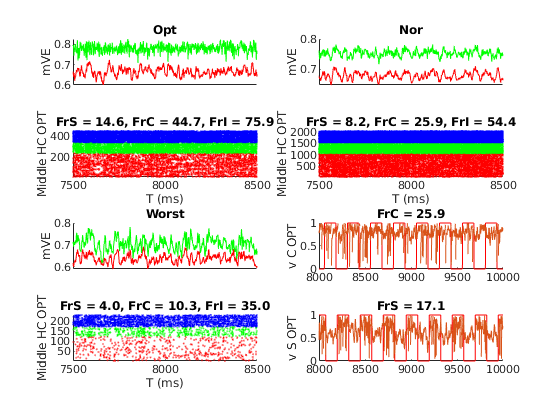

OptE = [L6SFilt>0.93*max(L6S_Drive);  L6CFilt>0.93*max(L6C_Drive)]';
OptI =  L6IFilt'>0.93*max(L6I_Drive);
WorstE = [L6SFilt<1.1*min(L6S_Drive);  L6CFilt<1.1*min(L6C_Drive)]';
WorstI =  L6IFilt'<1.1*min(L6I_Drive);
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1*n_S_HC & NnS.X<=2*n_S_HC;
MidRowS = NnS.Y>=1*n_S_HC & NnS.Y<=2*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1*n_C_HC & NnC.X<=2*n_C_HC;
MidRowC = NnC.Y>=1*n_C_HC & NnC.Y<=2*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1*n_I_HC & NnI.X<=2*n_I_HC;
MidRowI = NnI.Y>=1*n_I_HC & NnI.Y<=2*n_I_HC;
MidHCI= MidColI & MidRowI;

% SOpt = find(OptE & ~EcplxInd);
% scatterSOpt = find(ismember(SpE(:,1), SOpt));
% [~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
% FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);
%
% COpt = find(OptE & EcplxInd);
% scatterCOpt = find(ismember(SpE(:,1), COpt));
% [~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
% FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [7500 8500];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);

### Plot Spatial maps: Plot

WinSize = 9000;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));


Determine On and Off t for Frs and mVs: 

Note, we get rid of the first 10ms of each interval

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
PhaseExc = 20;
mVPh = mod(repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), tMod);
OnOffmV = ~logical(floor(mVPh/MaxOnPhase)); % 1 for all on period, 0 for all off
OnmV  =  OnOffmV & ~(0< mVPh & mVPh<PhaseExc);
OffmV = ~OnOffmV & ~(MaxOnPhase< mVPh & mVPh<MaxOnPhase+PhaseExc);

SpPh = mod(PhaseE(SpE(:,1)) - T + SpE(:,2),tMod);
OnOffSpE =  ~logical(floor(SpPh/MaxOnPhase));
% OnSpE  =  OnOffSpE & ~(0<SpPh & SpPh<PhaseExc);
% OffSpE = ~OnOffSpE & ~(MaxOnPhase<SpPh & SpPh<MaxOnPhase+PhaseExc);
% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

% NnS.X = NnE.X(~EcplxInd); NnS.Y = NnE.Y(~EcplxInd);
% NnC.X = NnE.X(EcplxInd); NnC.Y = NnE.Y(EcplxInd);

FrERan = [0 55];
mVERan = [0.62 0.80];

Figure for ONOFF

First create an onoff vec for each spike

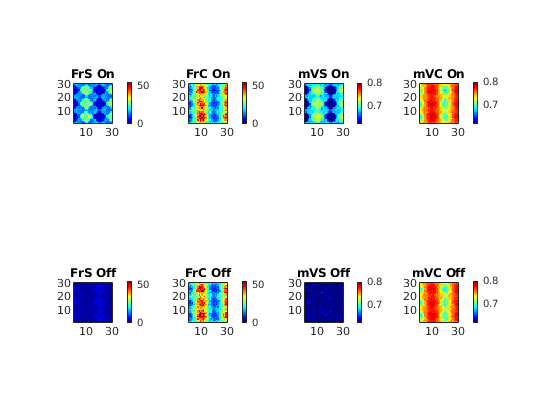

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates:S
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrSOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOnPixMat); title('FrS On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrSOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOffPixMat); title('FrS Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

% Firing rates: C
subplot 242
[FrCOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOnPixMat); title('FrC On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 246
[FrCOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOffPixMat); title('FrC Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% mVs: S
OnmVPhase = double(OnmV);
OnmVPhase(~OnmV) = nan;
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

subplot 243
[mVSOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOnPixMat); title('mVS On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

OffmVPhase = double(OffmV);
OffmVPhase(~OffmV) = nan;
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

subplot 247
[mVSOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOffPixMat); title('mVS Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

% mVs: C
subplot 244
[mVCOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOnPixMat); title('mVC On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

subplot 248
[mVCOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOffPixMat); title('mVC Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

Figure for All Average

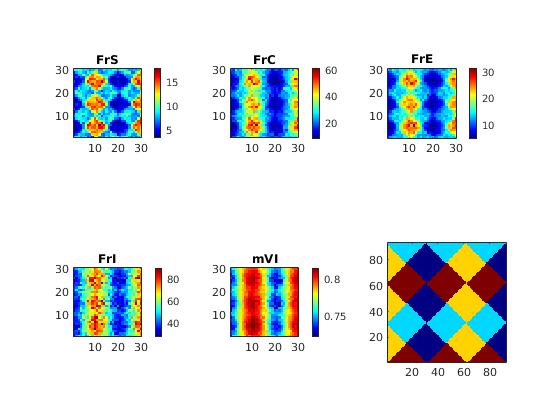

hFrVAll = figure('Name','Field_f&V');
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
%FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

subplot 231
[FrSPixMat,NnSPixel] = NeuVec2Pixel(FrE_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSPixMat); title('FrS')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar
subplot 232
[FrCPixMat,NnCPixel] = NeuVec2Pixel(FrE_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCPixMat); title('FrC')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(FrSPixMat*(1-CplxR)+ FrCPixMat*CplxR);
title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
% subplot 233
% imagesc(OD_EMap);axis square
% set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

Complex % Simple spikes

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
hSpCount = figure('Name','SpCountE')

hSpCount =   Figure (45: SpCountE) with properties:

      Number: 45
        Name: 'SpCountE'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


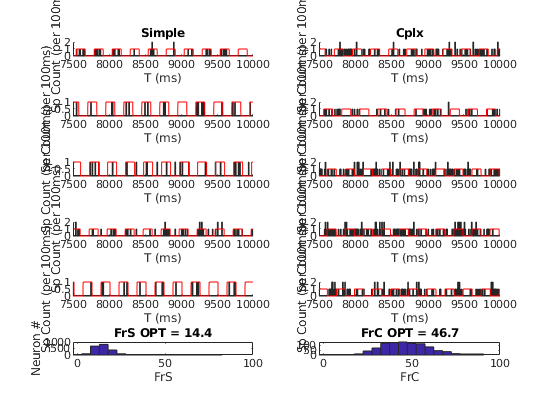

USE = [1,50,300,1000 1500];
for subInd = 1:5
    subplot(6,2,2*subInd-1)
    NeuInd = OPTS(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    if subInd ==1
        title('Simple')
    end

    subplot(6,2,2*subInd)
    NeuInd = OPTC(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')

    if subInd ==1
        title('Cplx')
    end

end
OPTS = OptE & ~EcplxInd;
OPTC = OptE & EcplxInd;
subplot(6,2,11)
hist(FrE_temp(OPTS),0:5:80)
title(sprintf('FrS OPT = %.1f', mean(FrE_temp(OPTS))))
xlabel('FrS'); ylabel('Neuron #')
subplot(6,2,12)
hist(FrE_temp(OPTC),0:5:80)
title(sprintf('FrC OPT = %.1f', mean(FrE_temp(OPTC))))
xlabel('FrC')

%save('DriveWkSp.mat')

### A5. MF linear equation for pixels: 1 Matrices

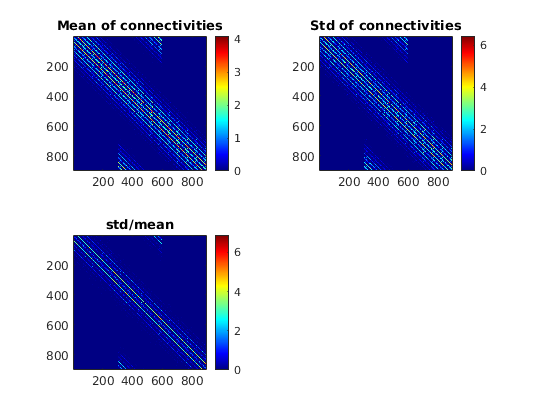

clear ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
    OffmVPhase OnmVPhase OnOffmV OnOffSpE...
    SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
    mVE mVEOff mVEOn mVI

load(['ConnPixel_Cconst.mat'])
% Present connectivity mats
figure
subplot 221
imagesc(C_SS_Pixel_Us)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_CS_Pixel_Us)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_CI_Pixel_Us)
axis square
colorbar
title('std/mean')


PixNum = NPixX*N_HC * NPixY*N_HC;
FrSPixVec    = reshape(FrSPixMat,  PixNum,1);
FrSOnPixVec  = reshape(FrSOnPixMat,PixNum,1);
FrSOffPixVec = reshape(FrSOffPixMat,PixNum,1);
FrCPixVec    = reshape(FrCPixMat,  PixNum,1);
FrCOnPixVec  = reshape(FrCOnPixMat,PixNum,1);
FrCOffPixVec = reshape(FrCOffPixMat,PixNum,1);
FrIPixVec    = reshape(FrIPixMat,  PixNum,1);

mVSOnPixVec  = reshape(mVSOnPixMat,PixNum,1);
mVSOffPixVec = reshape(mVSOffPixMat,PixNum,1);
mVCOnPixVec  = reshape(mVCOnPixMat,PixNum,1);
mVCOffPixVec = reshape(mVCOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_SOn_Pixel = zeros(PixNum,1);
lambda_SOff_Pixel = zeros(PixNum,1);
lambda_COn_Pixel = zeros(PixNum,1);
lambda_COff_Pixel = zeros(PixNum,1);
L6S_Pixel = zeros(PixNum,1);
L6C_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
lambda_SOn_drive = lambda_EOn_drive(~EcplxInd); lambda_COn_drive = lambda_EOn_drive(EcplxInd);
lambda_SOff_drive = lambda_EOff_drive(~EcplxInd); lambda_COff_drive = lambda_EOff_drive(EcplxInd);
rS_L6_Drive = rE_L6_Drive(~EcplxInd); rC_L6_Drive = rE_L6_Drive(EcplxInd);
for PixInd = 1:PixNum
    lambda_SOn_Pixel(PixInd)  = mean(lambda_SOn_drive(NnSPixel.Vec == PixInd));
    lambda_SOff_Pixel(PixInd) = mean(lambda_SOff_drive(NnSPixel.Vec == PixInd));
    lambda_COn_Pixel(PixInd)  = mean(lambda_COn_drive(NnCPixel.Vec == PixInd));
    lambda_COff_Pixel(PixInd) = mean(lambda_COff_drive(NnCPixel.Vec == PixInd));
    L6S_Pixel(PixInd) = mean(rS_L6_Drive(NnSPixel.Vec == PixInd));
    L6C_Pixel(PixInd) = mean(rC_L6_Drive(NnCPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive_Pre;

Below need work

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + 2*PixNum;
FrPreUse = FrSOffPixVec(FrPreUseDim - 2*PixNum);
%FrPreUse = FrEOffLIF(FrPreUseDim - PixNum);
FrPreUse = [];

### A6. Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
    C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
    C_SS_Fix_Bd C_SC_Fix_Bd C_CS_Fix_Bd C_CC_Fix_Bd...
    C_SI_Fix_Bd C_CI_Fix_Bd C_IS_Fix_Bd C_IC_Fix_Bd...
    COpt_Ind SOpt_Ind scatterCOpt scatterSOpt...
    ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
    OffmVPhase OnmVPhase OnOffmV OnOffSpE OnmV OffmV...
    SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood SpPh...
    mVE mVEOff mVEOn mVI ...
    NWTrace AmbE_Events AdjlgnE AmbI_Events CMatAll ...
    EampaInp EnmdaInp GE_ETemp GE_ITemp IampaInp InmdaInp ...
    L6E_Events L6I_Events lgnE_Events lgnI_Events...
    mVECurrent mVICurrent mVETemp mVPh
save([SaveFolder,'AllMFPixPara_Paper2TuneFig1V4.mat'])